# `figtitle`

This function creates a title centered at the top of a figure. This may be used to add a title to a figure with several subplots.

## Syntax

## Description

`figtitle('TitleString')` centers a title at the top of a figure and sets the figure name to `'TitleString'`. 

`figtitle('TitleString','TextProperty',TextValue)` formats the title with property name value pairs (e.g., `'FontSize',20`)

`h = figtitle(...)` returns a handle `h` of the newly-created title. 

## Example 1: Simple case.

Here we use `figtitle` for a simple case: 

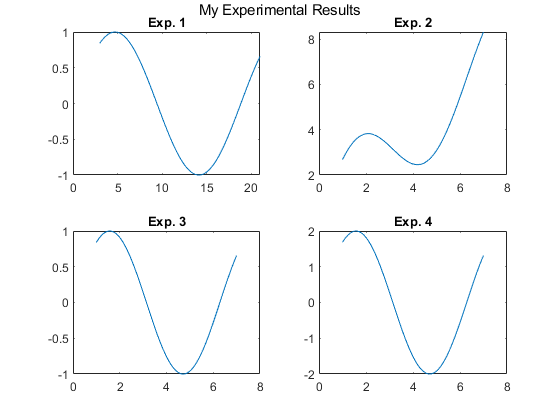

x = 1:.01:7; 
y = sin(x); 

figure; 
subplot(2,2,1)
plot(3*x,y)
title('Exp. 1') 

subplot(2,2,2)
plot(x,2*y+x)
title('Exp. 2') 

subplot(2,2,3)
plot(x,y)
title('Exp. 3') 

subplot(2,2,4)
plot(x,2*y)
title('Exp. 4') 

figtitle('My Experimental Results');

## Example 2: `figtitle` pairs nicely with `ntitle`

When using `figtitle`, it may be nice to also use [`ntitle`](http://www.mathworks.com/matlabcentral/fileexchange/42114-ntitle). 

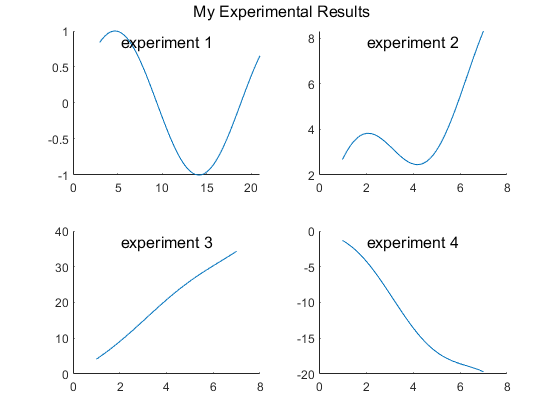

x = 1:.01:7; 
y = sin(x); 

figure; 
subplot(2,2,1)
plot(3*x,y)
ntitle('experiment 1','fontsize',12)
box off

subplot(2,2,2)
plot(x,2*y+x)
ntitle('experiment 2','fontsize',12)
box off

subplot(2,2,3)
plot(x,-y+5*x)
ntitle('experiment 3','fontsize',12)
box off

subplot(2,2,4)
plot(x,2*y-3*x)
ntitle('experiment 4','fontsize',12);
box off

h = figtitle(' My Experimental Results');

You may want a fancy `figtitle`. In the example above we returned a handle `h` of the `figtitle` because now we're going to delete the `figtitle` we just created and make a fancier one. 

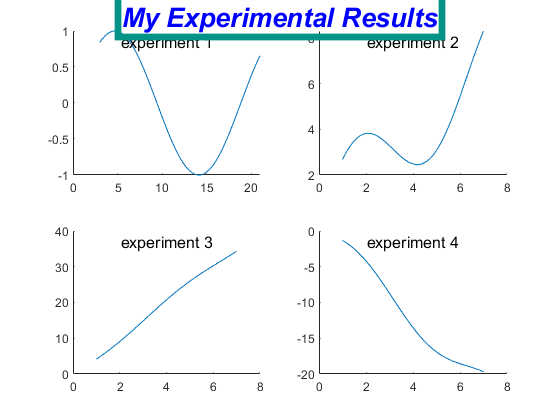

delete(h) 
figtitle('My Experimental Results',...
    'fontweight','bold',...
    'fontangle','oblique',...
    'edgecolor',[.007 .577 .526],...
    'color','blue',...
    'linewidth',5,...
    'fontsize',20);

Unfortunately, the `publish` command in Matlab makes the figures above look pretty lousy. When you use `figtitle` you'll have much better results than what is shown above--particularly if you export your graphics via  [`export_fig`](http://www.mathworks.com/matlabcentral/fileexchange/23629-export-fig). 

## Author Info

Written by Chad A. Greene of the University of Texas at Austin Institute for Geophysics, July 2013. 

Updated August 2014 to include support for invisible figures and now also sets the figure name to the title string. 